# Example Script Associated with:

# Speed of sound of pure water to 700 MPa and 

# an equation of state to 2300 MPa.

# by O. Bollengier, J.M. Brown, and G. Shaw

The following demonstrates the use of a "Local Basis Function" (LBF) representation for the equation of state of water using the numerical environment of MATLAB.  

Requirements: (1) a recent MATLAB version that allows use of "live scripts"

                         (2) Curve Fitting Toolbox (available for a 30 day free trial if not installed)

                                 note: since the LBFs use tensor spline basis functions, two Toolbox functions are required:

                                          fnval:     evaluates a spline either from scattered data or gridded data

                                          fnder:    returns a specified derivative of a spline representation

                         (3)  a data file: "WaterEOS" in the MATLAB path.  This file contains both a collection of relevant 

                                     data and the LBF representation

                         (4) three custom MATLAB functions 

                                           fnGval:  evaluates thermodynamic properties using the LBF for Gibbs Energy

                                           therm_surf: creates 3D thermmdynamic surfaces as a function of P and T

                                          IAPWS95: returns properties based on the IAPWS-95 representation

Units: MPa for pressure, K for temperature, S.I. units for density, Cp, and G (kg, J, m)

The individual code block below can be executed individually by clicking on the left side bar or by using the "Run" button at the top. Comments are highlighted in green

In the first section the data are loaded into the environment and the content is described

clear  % clear all local variables to begin with a clean slate

load WaterEOS
% Below this the data content is displayed by typing the name of the structure 
% containing the data: Sound Speeds (SS), melt line (melt), densities 
% (rho), and constant pressure specific heats (Cp)
H2O

H2O = struct with fields:
      SS: [1×1 struct]
    melt: [1×1 struct]
     rho: [1×1 struct]
      Cp: [1×1 struct]


% within each of the stuctures within H2O, there are data and sources
% use a period and label to see what is contained. (note that the present
% (UW) data set is separated into separate runs in the sources)
H2O.SS

ans = struct with fields:
       data: [1421×6 double]
    sources: {'UW 1'  'UW 2'  'UW 3'  'UW 4'  'UW 5'  'UW 6'  'Lin and Trusler (2012)'  'Abramson and Brown (2004)'  'Decremps et al. (2006)'  'Sanchez Valley et al. (2013)'}


% the data are organized in matrixes with each line containing
%   "pressure temperature value uncertainty(ppm) IAPWS95   source" 
%      source is a number associated with the numbered order in "sources" 
H2O.SS.data(1,:)

ans =        441.09       313.95       2173.5          200       2171.1            1


% the LBF is contained within the structure G_H2O_2GPa_500K where the range
% of coverage is incorporated into the name.  Here is the content
G_H2O_2GPa_500K

G_H2O_2GPa_500K = struct with fields:
      form: 'B-'
     knots: {[1×86 double]  [1×46 double]}
    number: [80 40]
     order: [6 6]
       dim: 1
     coefs: [80×40 double]
      PTmc: {[1×80 double]  [1×40 double]}


% the first 6 elements of the structure are standard for MATLAB
% representations of tensor splines. See MATLAB documentation for more information
% The last element PTmc is added in the current work. It records the choice of 
% "control points" used during the construction of the representation.  This 
% information is only relevant in the case of future revisions of the
% representation and is not used here.


In this section, methods to extract thermodynamic properties from the LBF representation are demonstrated

The basic syntax for use of the representations is:

               output=fnGval(LBF,PT);

where:

                PT is either a grid of pressures and temperatures (T increasing across and P increasing down) 

            or PT is a column matrix of scattered PT points (P in column one and T in column 2).

              output is a structure containing all calculated thermodynamic properties

              LBF is the structure containing the local basis function representation for Gibbs energy

Begin using the  "scattered data" form of data entry

% start with a very simple case: properties at STP (P=0.1 MPa, T=300 K)
% (brackets concatenate values into a single array)
out=fnGval(G_H2O_2GPa_500K,[0.1,300])

out = struct with fields:
      rho: 996.56
       Cp: 4180.6
        G: -5267.3
       Cv: 4130.1
      vel: 1501.5
       Kt: 2219.7
       Ks: 2246.8
       Kp: 5.6287
        S: 393.06
        U: 1.1255e+05
        H: -5367.6
    alpha: 0.00027479


% for comparison, here is the same information based on IAPWS-95
% this function can use either P-T input (flg: 'P') or density-T (flg: 'V')
outIAPWS=IAPWS95([0.1,300],'P')

outIAPWS = struct with fields:
      rho: 996.56
      vel: 1501.5
        G: -5265.2
       Cp: 4180.8
       Cv: 4130.3
       Kt: 2219.7
    alpha: 0.0002748
        S: 393.07
        U: 1.1256e+05
        H: 1.1266e+05
    gamma: 0.1482
        P: 0.1
        A: -5365.5


% Here is the IAPWS call using density as an input
outIAPWS=IAPWS95([996.56,300],'V')

outIAPWS = struct with fields:
      rho: 996.56
      vel: 1501.6
        G: -5257
       Cp: 4180.7
       Cv: 4130.3
       Kt: 2219.8
    alpha: 0.00027481
        S: 393.07
        U: 1.1256e+05
        H: 1.1266e+05
    gamma: 0.14821
        P: 0.10815
        A: -5365.5


% here is a simple example for scattered data - calculate properties for
% the pressures and temperatures of the actual data that were loaded. Do it
% for first 5 points to get the idea
out=fnGval(G_H2O_2GPa_500K,H2O.SS.data(1:5,1:2));% simicolon to supress output
%look at the output densities:
out.rho

ans =        1128.2
       1136.7
       1129.2
       1132.4
       1138.2


Now try gridded input.  The general syntax uses brackets: {P,T} where P and T are vectors of values (increasing) for each variable.  This example is for a very small grid:

P=[0.1 5 10];
T=[300 350 400 450];
out=fnGval(G_H2O_2GPa_500K,{P,T}); 
% examine the grid of densities (T across and P down)
out.rho

ans =        996.56       973.73       937.41       889.79
       998.75        975.9       939.91       892.99
         1001       978.09       942.42       896.17


% This data entry works using the IAPWS-95 code as well
out=IAPWS95({P,T},'P');
out.rho

ans =        996.56       973.73       937.41       889.79
       998.74        975.9       939.91       892.99
         1001       978.09       942.42       896.16


Now larger calculations of properties are undertaken and various surfaces plotted

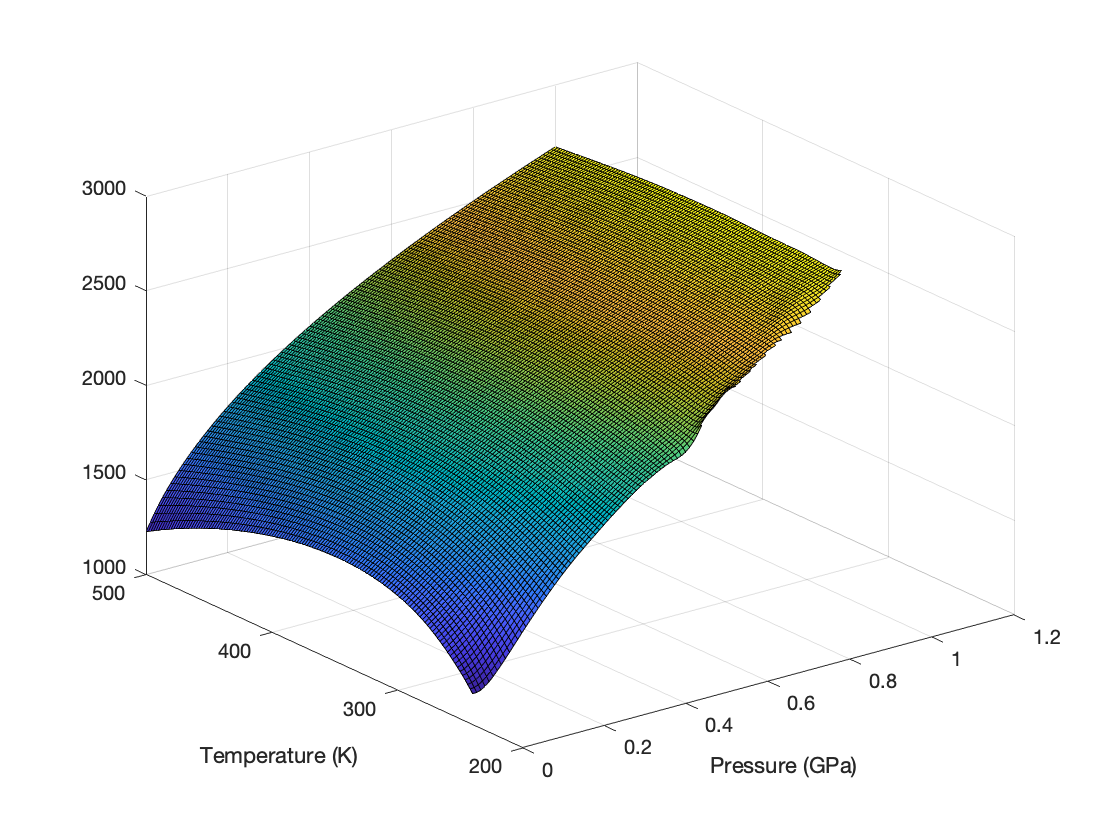

% creat the plotting grid of pressures and temepratures:
P=0.1:10:1000.1;  % a vector of pressures in steps of 10 to 1000
T=240:2:500;  % a vector of temperatures
PT={P,T};  % combine for convenience into a single structure
% a small complication: all EOSs fail in the deeply metastable regime at
% high pressures.  We need to mask off the problem areas.  
% Here is a small code segment to create a mask:
Tcut=30; % let the representation extend 30 K into the metastable region
mask=ones(length(PT{1}),length(PT{2}));
    Tm=interp1(H2O.melt.data(:,1),H2O.melt.data(:,2),PT{1});
    i_p_range=find(PT{1}>200);
    for i=i_p_range
        idm=find(PT{2}<(Tm(i)-Tcut));
        if (not(isempty(idm)))
            mask(i,idm)=NaN;       
        end
    end

% calculate the EOS properties
out=fnGval(G_H2O_2GPa_500K,PT);
% plot the sound speeds
therm_surf(PT,real(out.vel),mask)

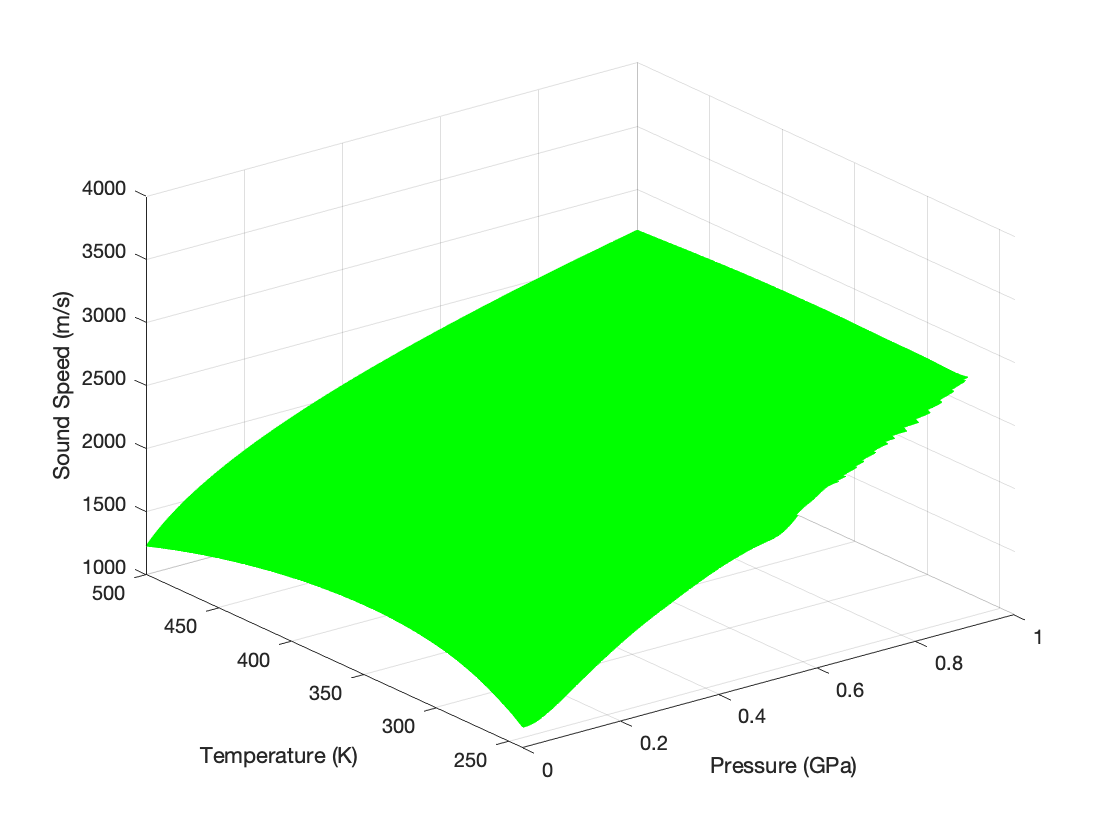

% the therm_surf function has a variety of additional optional inputs including
% z-labels, axes limits and surface colors
therm_surf(PT,real(out.vel),mask,'Sound Speed (m/s)',[0 1000 240 500 1000 4000],'g')

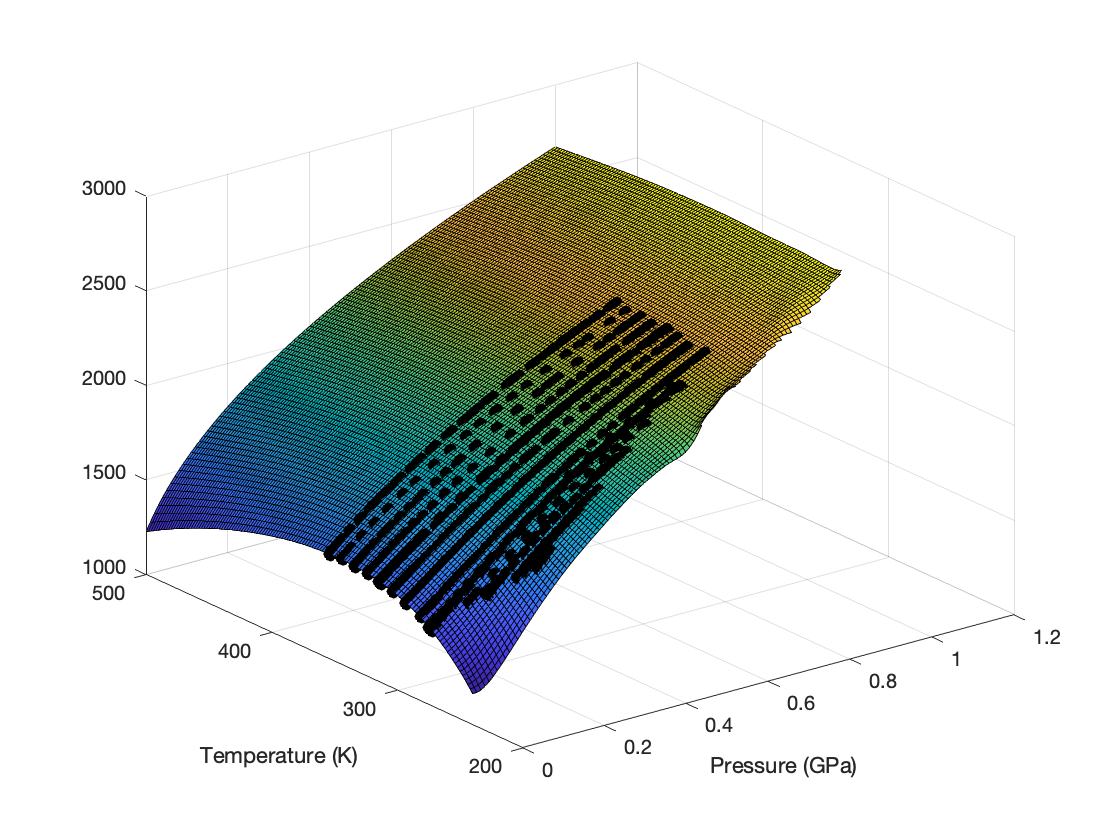


% UW data can be plotted on the same surface:

id=find(H2O.SS.data(:,6)<7);

therm_surf(PT,out.vel,mask)
hold on
plot3(H2O.SS.data(id,1)/1e3,H2O.SS.data(id,2),H2O.SS.data(id,3),'ko','MarkerFaceColor','k')
hold off

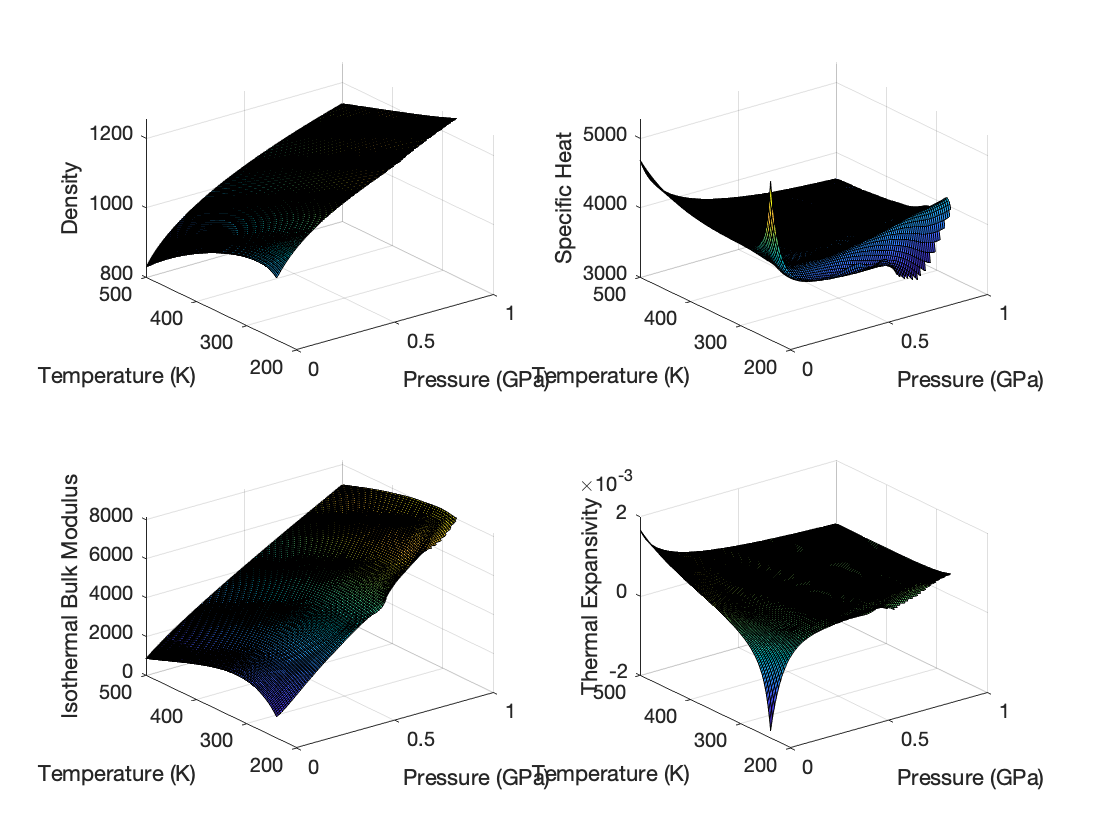

% plot Cp thermal expansivity
subplot(111)
subplot(221)
therm_surf(PT,out.rho,mask,"Density")
subplot(222)
therm_surf(PT,out.Cp,mask,"Specific Heat")
subplot(223)
therm_surf(PT,out.Kt,mask,"Isothermal Bulk Modulus")
subplot(224)
therm_surf(PT,out.alpha,mask,"Thermal Expansivity")


subplot(111)